%QUESTION 1
alpha=1+mod(163,3)

alpha = 2

f1=10;
f2=20;
fs=720;
wp=10/360;
ws=20/360;
[n,wn]=buttord(wp,ws,2,40)

n = 8

wn = 0.0313

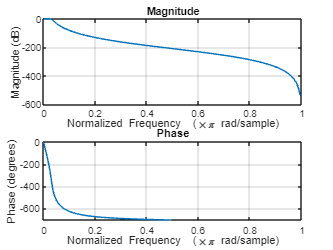

[b,a]=butter(n,wn);
subplot(2,1,1)
freqz(b,a)



% tf
sys1=tf(b,a,720)

sys1 =
 
                                                                                                
  2.668e-11 z^8 + 2.134e-10 z^7 + 7.47e-10 z^6 + 1.494e-09 z^5 + 1.867e-09 z^4 + 1.494e-09 z^3  
                                                                                                
                                                        + 7.47e-10 z^2 + 2.134e-10 z + 2.668e-11
                                                                                                
  ----------------------------------------------------------------------------------------------
                                                                                               
   z^8 - 7.496 z^7 + 24.6 z^6 - 46.15 z^5 + 54.15 z^4 - 40.69 z^3 + 19.12 z^2 - 5.136 z + 0.604
                                                                                               
 
Sample time: 720 seconds
Discrete-time transfer function.



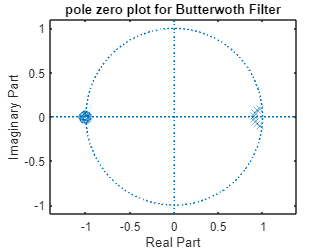

zplane(b,a)
title('pole zero plot for Butterwoth Filter');

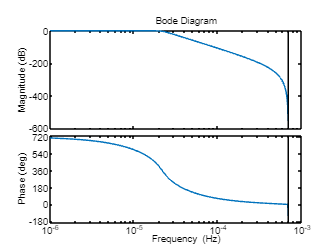


%bode plot
options = bodeoptions;
options.FreqUnits = 'Hz';
bode(sys1,options)

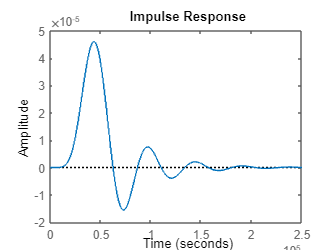


%impulse response
impulse(sys1)

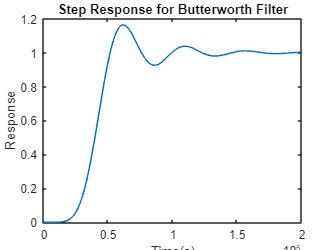


%step response
[y1,t]=step(sys1);
plot(t,y1)
xlabel('Time(s)');
ylabel('Response');
title('Step Response for Butterworth Filter');


%QUESTION 4------------------------------------------------------
[n1,wn1]=cheb1ord(wp,ws,2,40)

n1 = 5

wn1 = 0.0278

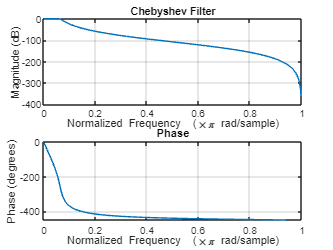

[b1,a1]=cheby1(n1,wp,ws);
subplot(2,1,1)
freqz(b1,a1)
title('Chebyshev Filter');


%transfer function
sys2=tf(b1,a1,720)

sys2 =
 
  3.261e-06 z^5 + 1.631e-05 z^4 + 3.261e-05 z^3 + 3.261e-05 z^2 + 1.631e-05 z + 3.261e-06
  ---------------------------------------------------------------------------------------
                z^5 - 4.575 z^4 + 8.422 z^3 - 7.793 z^2 + 3.625 z - 0.6777
 
Sample time: 720 seconds
Discrete-time transfer function.



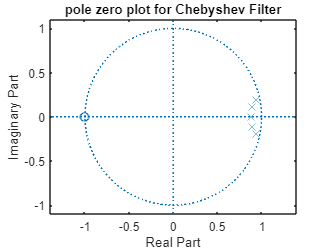

zplane(b1,a1)
title('pole zero plot for Chebyshev Filter');

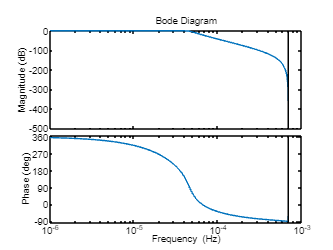


%Bode plot
options = bodeoptions;
options.FreqUnits = 'Hz';
bode(sys2,options)

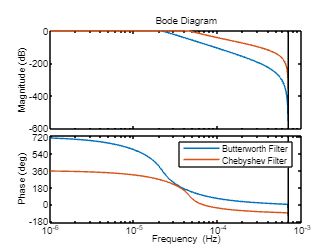

bode(sys1,sys2,options)
legend('Butterworth Filter','Chebyshev Filter');

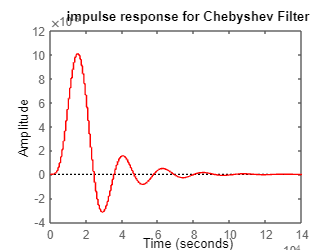


%impulse response
impulse(sys2,'r')
title('impulse response for Chebyshev Filter')

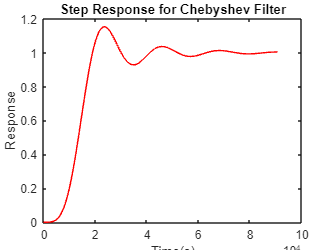


%step response
[y2,t]=step(sys2);
plot(t,y2,'r')
xlabel('Time(s)');
ylabel('Response');
title('Step Response for Chebyshev Filter');


%butterworth vs chebyshev impulse and step responses

h1=impulseplot(sys1,sys2)


h1 =

	resppack.timeplot



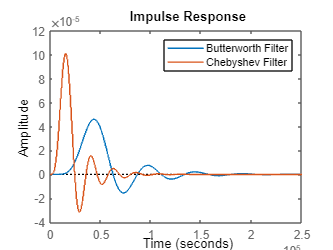

legend('Butterworth Filter','Chebyshev Filter');


h2=stepplot(sys1,sys2)


h2 =

	resppack.timeplot



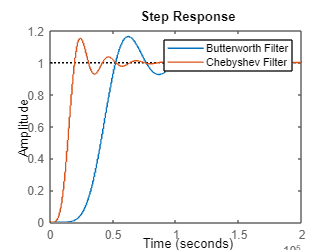

legend('Butterworth Filter','Chebyshev Filter');


%Question 2---------------------------------------------------
myfile='ECG_Data.txt'

myfile = "C:\Users\vishn\OneDrive\Desktop\Experiment-6\Experiment-6\ECG_Data.txt"

delimiter='\t';
data=importdata(myfile,delimiter);
f1=10;
f2=20;
fs=720;
wp=10/360;
ws=20/360;
[n,wn]=buttord(wp,ws,2,40)

n = 8

wn = 0.0313

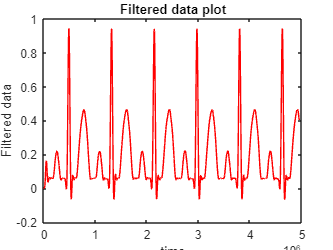

[b,a]=butter(n,wn);
filtered_data=filter(b,a,data);
filtered_file='filtered_data.txt';
dlmwrite(filtered_file,filtered_data,'delimiter','\t');
t=linspace(0,(length(filtered_data)-1)*720,length(filtered_data));
plot(t,filtered_data,'r')
xlabel('time');
ylabel('Filtered data');
title('Filtered data plot');


%Question 3
[s,Fs]=audioread('instru2.wav');
N=1500

N = 1500

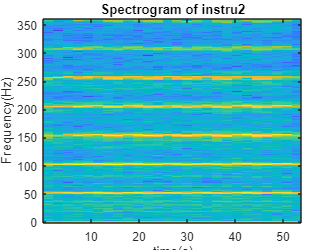

[s,f,t]=spectrogram(s,hanning(N),10,500,fs);
imagesc(t,f,10*log10(abs(s)))
axis xy;
xlabel('time(s)');
ylabel('Frequency(Hz)');
title('Spectrogram of instru2');

                                               
Fn = Fs/2;                                                  
Wp = [2250 2300]/Fn;                                           
Ws = [2240 2320]/Fn;                                           
Rp =  1;                                                    
Rs = 60;                                                    
[n,Wn] = buttord(Wp, Ws, Rp, Rs);                           
[b,a] = butter(n, Wn,'bandpass'); 
filteredinstru=filter(b,a,s);
audiowrite('Filteredinstrument.wav',filteredinstru,Fs)

Error using audiowrite
Expected input to be real.


[s1,fs1]=audioread('Filtered_instrument.wav');
[S,F,T]=spectrogram(s1,hanning(N),10,500,fs1);
imagesc(T,F,10*log10(abs(s1)));
axis xy;
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Spectrogram of filtered instrument');
